# ** GRN Project 2**

Five gene regulatory network motifs are simulated in the code `GRNs_for_HW2.m`. These are:

- Direct negative feedback

- Indirect negative feedback

- Double negative feedback

- Incoherent feed-forward

- Repressilator

For most gene regulatory motifs, as an activating input is increased, the steady-state amount of protein increases gradually. The *biological function* of "ultrasensitivity" or "switch-like response" is a phenomena where the steady-state amount of protein increases slowly, then suddenly, then slowly again. 

# HW2 

Find at least one of the 5 network motifs listed above that produces a switch-like response. Plot the amount of protein as a function of input concentration, showing the switch-like graph.

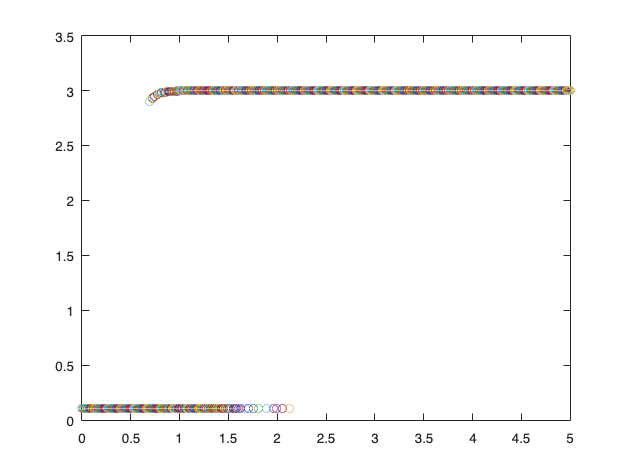

%% 5.0 ----- DOUBLE NEGATIVE FEEDBACK -----

for p=(0:.001:5)

    Kba = p; % inhibition of A by B
    Kaa = 0;
    
    Kab = 1; % inhibition of B by A
    Kbb = 0;

    delta_ma = 1;
    gamma_pa = 1;
    delta_pa = 1;
    
    delta_mb = 1;
    gamma_pb = 1;
    delta_pb = 1;
    
    gamma_ma =@(pb) 3./(1+abs(Kba*pb).^3);
    gamma_mb =@(pa) 3./(1+abs(Kab*pa).^3);

    dmadt =@(ma,pa,mb,pb,t) +gamma_ma(pb) - delta_ma*ma;
    dpadt =@(ma,pa,mb,pb,t) +gamma_pa*ma - delta_pa*pa;
    
    dmbdt =@(ma,pa,mb,pb,t) +gamma_mb(pa) - delta_mb*mb;
    dpbdt =@(ma,pa,mb,pb,t) +gamma_pb*mb - delta_pb*pb;

    dxdt = @(t,x)[dmadt(x(1),x(2),x(3),x(4),t);
                  dpadt(x(1),x(2),x(3),x(4),t);
                  dmbdt(x(1),x(2),x(3),x(4),t);
                  dpbdt(x(1),x(2),x(3),x(4),t)];
    
    
    initialCondition = 2*rand(4,1);
    

    [T, X] = ode45(dxdt, [0.0,1000], initialCondition);
    plot(p,X(end),'o')
    hold on

end

hold off